clc; clear all; close all;


A = [1 2 1 3; 1 -2 1 2; 2 4 2 1; 5 4 3 1]

A =      1     2     1     3
     1    -2     1     2
     2     4     2     1
     5     4     3     1


B = [2 1; 1 1; 9 2; 0 0]

B =      2     1
     1     1
     9     2
     0     0


Csen = [1 1 1 0; 1 0 0 1; 1 1 0 4]

Csen =      1     1     1     0
     1     0     0     1
     1     1     0     4


Dsen = zeros(3, 2)

Dsen =      0     0
     0     0
     0     0



% Salida que deseamos
Csal = [0 1 0 0];
Dsal = zeros(1, 2);

nx = size(A, 1);
ny = size(Csal, 1);
nu = size(B, 2);

% Sistema Aumentado
AOL = [A zeros(nx, ny); 
    -Csal zeros(ny, ny)];
BOL = [B; zeros(ny, nu)];

% Diseño del LQR con integrador
QOL = diag([1 1 1 1 10000]);
ROL = eye(nu) * 0.001;         
KOL = lqr(AOL, BOL, QOL, ROL);

K = KOL(:, 1:nx)

K =    93.4460  -64.1961   19.3959   65.6285
    0.7687   94.0061   -3.0558    2.2495


Ki = -KOL(:, (nx+1):end)

Ki = 1.0e+03 *

   -0.3359
    3.1444



Cy = [Csen;Csal]

Cy =      1     1     1     0
     1     0     0     1
     1     1     0     4
     0     1     0     0


% Diseño del observador (LQE)
Gw = eye(nx)

Gw =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Qw = 0.001*eye(nx); 
Vv = 0.0001*eye(size(Cy, 1)); 
L = lqe(A, Gw, Cy, Qw, Vv)

L =     0.9394    2.4297    2.0995   -0.1555
    1.3447   -0.0396    1.5455    1.2373
    4.9132   -0.3878    2.8906    0.2629
    1.0629    0.9381    4.0430    0.1159



[L.*[Csen;Csal] A-B*K-L.*[Csen;Csal] B*Ki]

ans = 1.0e+03 *

    0.0009    0.0024    0.0021         0   -0.1876    0.0340   -0.0368   -0.1305    2.4727
    0.0013         0         0    0.0012   -0.0946   -0.0318   -0.0153   -0.0671    2.8085
    0.0049   -0.0004         0    0.0011   -0.8455    0.3941   -0.1665   -0.5952    3.2660
         0    0.0009         0         0    0.0050    0.0031    0.0030    0.0010         0


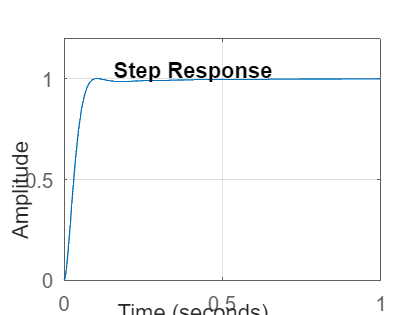

% Cierre del lazo
ACL = [A -B*K B*Ki;
      L.*Cy A-B*K-L.*Cy B*Ki;
       -Csal Dsal*K -Dsal*Ki];

BCL = [zeros(nx, ny);
        zeros(nx, ny);
        eye(ny)];

CCL = [Csal -Dsal*K Dsal*Ki];
DCL = zeros(ny);


GCL = ss(ACL, BCL, CCL, DCL);
step(GCL,1);
grid on;